# Deeplearning

## Pretrainmodel

trainData = readtable("Ped-Bro.xlsx")

trainData = 1366×3 table
    Position1    Position2    Classification
    _________    _________    ______________

        501         1025          {'F'}     
       1001         2049          {'F'}     
       1501         3073          {'F'}     
       2001         4097          {'F'}     
       2501         5121          {'F'}     
       3001         7169          {'N'}     
       3501         8193          {'F'}     
       4001         9217          {'F'}     
       4501        10241          {'F'}     
      12001        11265          {'F'}     
      12501        12289          {'F'}     
      13001        13313          {'F'}     
      13501        14337          {'F'}     
      14001        15361          {'F'}     
      14501        16385          {'F'}     
      15001        17409          {'F'}     


trainFeatures = generateFeatures(trainData);
head(trainFeatures)

    Classification    Position1    Position2
    ______________    _________    _________

        {'F'}            501         1025   
        {'F'}           1001         2049   
        {'F'}           1501         3073   
        {'F'}           2001         4097   
        {'F'}           2501         5121   
        {'N'}           3001         7169   
        {'F'}           3501         8193   
        {'F'}           4001         9217   



summary(trainFeatures)


trainFeatures: 1366×3 table

Variables:

    Classification: cell array of character vectors
    Position1: double
    Position2: double

Statistics for applicable variables:

                      NumMissing      Min         Median           Max             Mean              Std      

    Classification        0                                                                                   
    Position1             0            501        2196251        4177001        2.1439e+06        1.2071e+06  
    Position2             0           1025        1417729        2879489        1.4082e+06        8.2854e+05  



trainFeatures.Classification = categorical(trainFeatures.Classification);

trainFeatures.Position1 = (trainFeatures.Position1 - mean(trainFeatures.Position1)) / std(trainFeatures.Position1);
trainFeatures.Position2 = (trainFeatures.Position2 - mean(trainFeatures.Position2)) / std(trainFeatures.Position2);

trainFeatures.Duration = trainFeatures.Position2 - trainFeatures.Position1;

labelCounts = countcats(trainFeatures.Classification);
disp(labelCounts);

         361
        1005



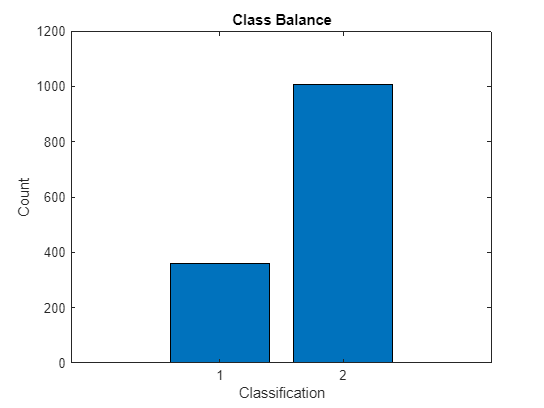

bar(labelCounts);
title('Class Balance');
ylabel('Count');
xlabel('Classification');

cv = cvpartition(height(trainFeatures), 'HoldOut', 0.2);  % 80-20 split
trainData = trainFeatures(training(cv), :);
testData = trainFeatures(test(cv), :);

% Generate duration feature
trainData.Duration = trainData.Position2 - trainData.Position1;
testData.Duration = testData.Position2 - testData.Position1;

% Prepare features and labels
% Extract features and labels
X_train = trainData{:, {'Position1', 'Position2', 'Duration'}};
y_train = trainData.Classification;

X_test = testData{:, {'Position1', 'Position2', 'Duration'}};
y_test = testData.Classification;

layers = [
    featureInputLayer(3, 'Normalization', 'zscore')
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer];

options = trainingOptions('adam', ...
    'MaxEpochs', 30, ...
    'MiniBatchSize', 64, ...
    'Plots', 'training-progress', ...
    'ValidationData', {X_test, y_test});

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       79.69% |       75.09% |       0.6244 |       0.6379 |          0.0010 |
|       3 |          50 |       00:00:02 |       68.75% |       73.99% |       0.6075 |       0.5774 |          0.0010 |
|       6 |         100 |       00:00:03 |       79.69% |       75.46% |       0.5018 |       0.5743 |          0.0010 |
|       9 |         150 |       00:00:04 |       73.44% |       75.46% |       0.5796 |   

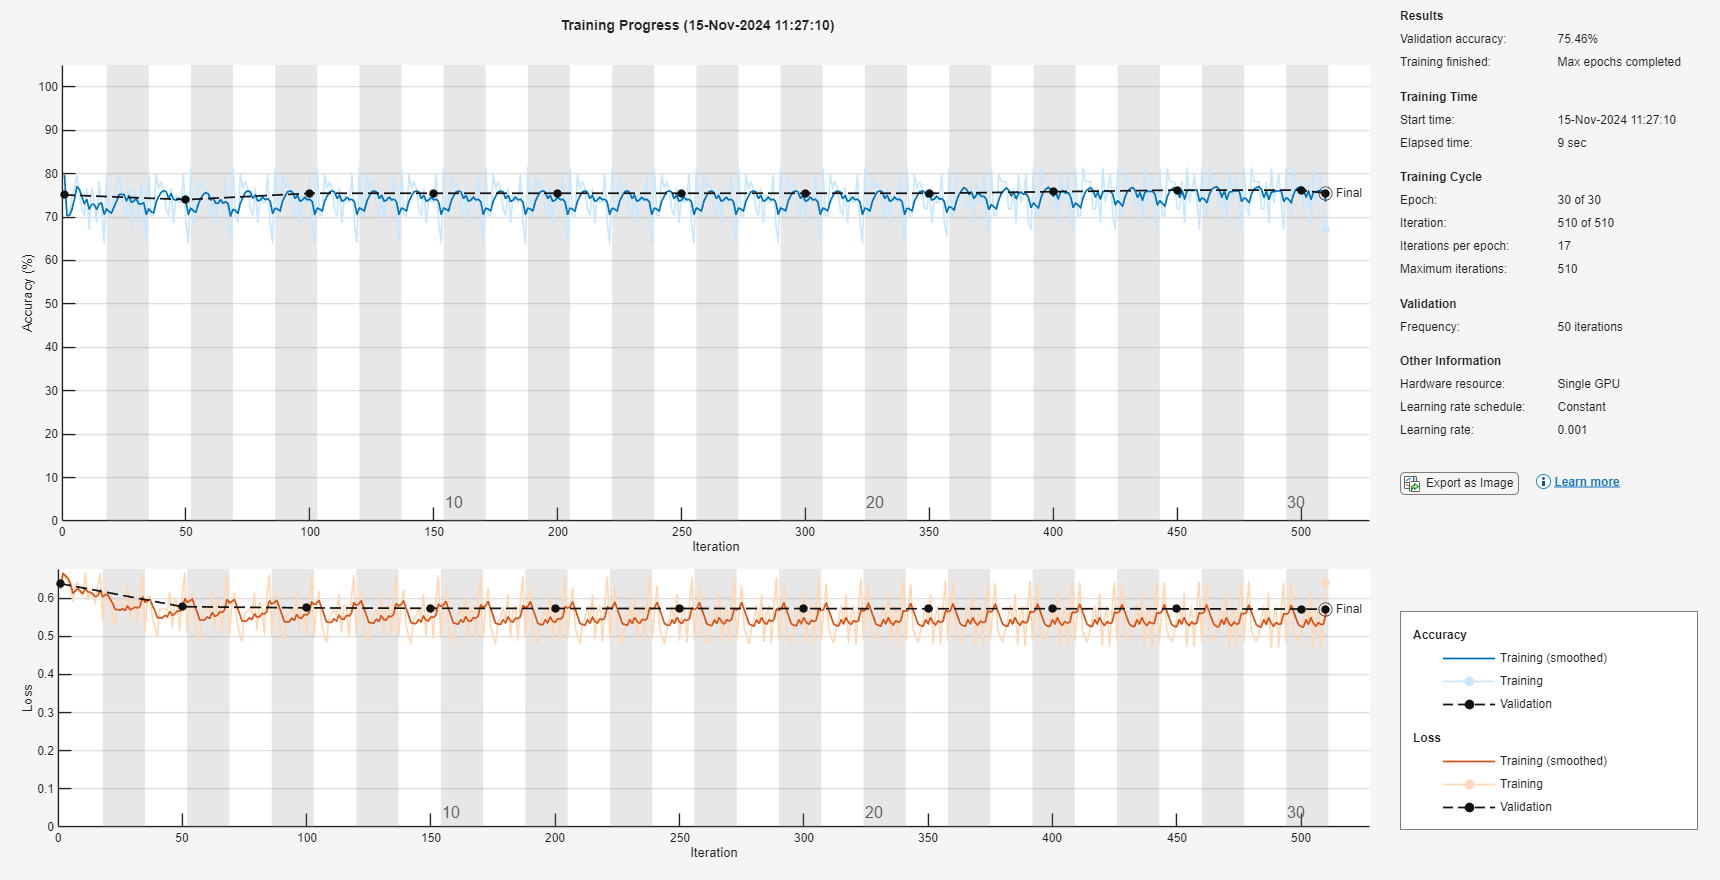

net = trainNetwork(X_train, y_train, layers, options);

% Example with SVM
model = fitcsvm(X_train, y_train);

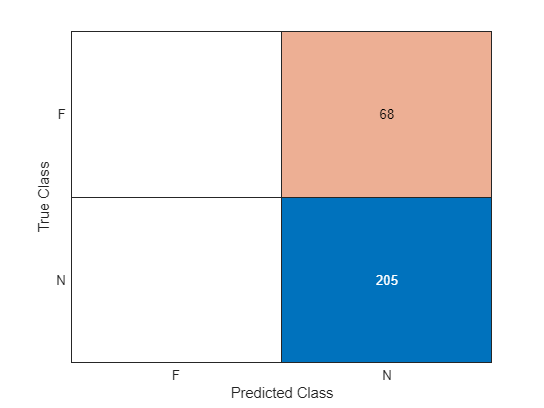

predictions = predict(model, X_test);

% Confusion Matrix
confusionchart(y_test, predictions);


% Accuracy
accuracy = sum(predictions == y_test) / length(y_test);
disp(['Model accuracy: ', num2str(accuracy)]);

Model accuracy: 0.75092


|==================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale | KernelFuncti-| PolynomialOr-|  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | on           | der          |              |
|==================================================================================================================================================|
|    1 | Best   |     0.26807 |     0.22192 |     0.26807 |     0.26807 |    0.0015514 |            - |   polynomial |            2 |        false |
|    2 | Accept |     0.26807 |    0.082274 |     0.26807 |     0.26807 |      0.14412 |            - |       linear |            - |         true |
|    3 | Accept |     0.26807 |     0.17912 |     0.26807 |     0.26807 |        122.2 |            - |   

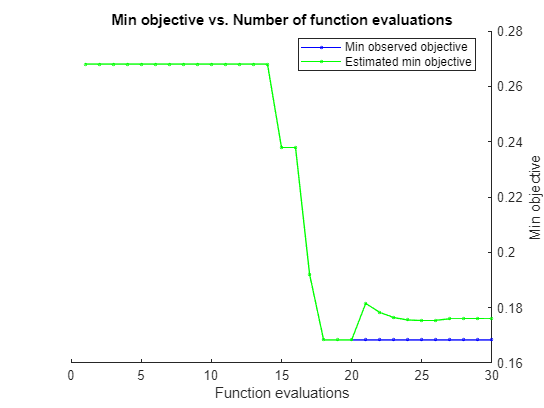

model = fitcsvm(X_train, y_train, 'OptimizeHyperparameters', 'all');